## 固定翼无人机三自由度TPBVP问题求解

动力学模型为：

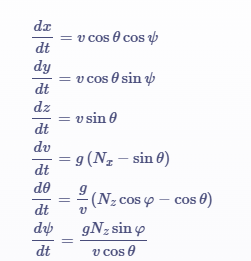

控制量选择：Nx Nz drolldt

状态量选择：x y z yaw pitch roll v

%function [trajectory, v, omega, a, cost] = SolveTPBVP3dim(startPose, goalPose, v0, vf, regionCons, dynamicCons, ifconspitchf)
% 调用GPOPSII求解三维空间的两点边值问题，获取一个运动基元
% 输入起始姿势、目标姿势、起始速度、目标速度、区域限制、动力学约束
% 输出一条轨迹和性能指标

% if nargin == 6
%     ifconspitchf = true;
% end
close all
clear
clc

startPose = [0 0 0 deg2rad(0) deg2rad(-10)]; % 起始位置和姿态：xyz和方向角、俯仰角
goalPose = [0 2000 200 deg2rad(0) deg2rad(0)];
speed = 30; % 定速飞行
v0 = speed;
vf = speed;

regionCons = [-200 5500; -200 5500; 0 1000]; % 飞行区域限制，依次为xyz的限制

dynamicCons.vmin = speed;
dynamicCons.vmax = speed;
dynamicCons.rollmin = -deg2rad(30); % 滚转角
dynamicCons.rollmax = deg2rad(30);
dynamicCons.pitchmin = -deg2rad(30); % 俯仰角
dynamicCons.pitchmax = deg2rad(30);
dynamicCons.yawmin = -2 * pi; % 偏航角
dynamicCons.yawmax = 2 * pi;
dynamicCons.Nxmin = 0; % 切向过载
dynamicCons.Nxmax = 1;
dynamicCons.Nzmin = -3; % 法向过载
dynamicCons.Nzmax = 3;
dynamicCons.drollmin = -2;
dynamicCons.drollmax = 2;

minR = speed^2/(9.8*tan(dynamicCons.rollmax));

t0 = 0;
xmin = regionCons(1, 1);
xmax = regionCons(1, 2);
ymin = regionCons(2, 1);
ymax = regionCons(2, 2);
zmin = regionCons(3, 1);
zmax = regionCons(3, 2);
tfmin = norm(startPose(1 : 3) - goalPose(1 : 3)) / dynamicCons.vmax;
tfmax = tfmin * 5;

## 设置约束条件

状态量：xyz坐标、航向角、俯仰角、滚转角、速度 控制量：切向过载、法向过载、滚转角速度

bounds.phase.initialtime.lower = t0;
bounds.phase.initialtime.upper = t0;
bounds.phase.finaltime.lower = tfmin;
bounds.phase.finaltime.upper = tfmax;
bounds.phase.initialstate.lower = [startPose 0 v0]; % 起始时刻状态上下限
bounds.phase.initialstate.upper = [startPose 0 v0];
bounds.phase.finalstate.lower = [goalPose 0 vf];
bounds.phase.finalstate.upper = [goalPose 0 vf];
% if ~ifconspitchf % 不给定终端角约束
%     bounds.phase.finalstate.lower(3) = dynamicCons.pitchmin;
%     bounds.phase.finalstate.upper(3) = dynamicCons.pitchmax;
% end
bounds.phase.state.lower = [xmin, ymin, zmin, dynamicCons.yawmin, dynamicCons.pitchmin, dynamicCons.rollmin, dynamicCons.vmin]; % 状态量约束
bounds.phase.state.upper = [xmax, ymax, zmax, dynamicCons.yawmax, dynamicCons.pitchmax, dynamicCons.rollmax, dynamicCons.vmax];
bounds.phase.control.lower = [dynamicCons.Nxmin dynamicCons.Nzmin dynamicCons.drollmin]; % 控制量约束
bounds.phase.control.upper = [dynamicCons.Nxmax dynamicCons.Nzmax dynamicCons.drollmax];
bounds.phase.integral.lower = 0; % 积分约束的最大最小值
bounds.phase.integral.upper = 1e10;

## 设置问题的初步猜测

实践证明结果对猜测很敏感

guess.phase.time = [t0; (tfmin + tfmax) / 2]; % 长度为Mp的列向量，Mp为时间猜测中使用的值的数量
guess.phase.state = [startPose 0 v0; goalPose 0 vf]; % 列数等于变量问题维数
% if ~ifconspitchf % 不给定终端角约束
%     guess.phase.state(2, 3) = atan2(goalPose(2) - startPose(2), goalPose(1) - startPose(1));
% end
% guess.phase.control = [uMin; uMax]; % 列数等于控制量u的维数
guess.phase.control = [0, 1, 0; 0, 1, 0];
guess.phase.integral = 100; % 行向量，长度为相位积分的数量

## 求解结构体设置

setup.name = 'OBVP-Problem';
setup.functions.continuous = @DynimicsModel;
setup.functions.endpoint = @CostFuncion;
setup.bounds = bounds;
setup.guess = guess;
setup.nlp.solver = 'snopt';
setup.derivatives.supplier = 'sparseCD';
setup.derivatives.derivativelevel = 'first';
% setup.scales.method = 'automatic-bounds';
setup.mesh.method = 'hp1';
setup.mesh.tolerance = 1e-3; % 网格精度
setup.mesh.maxiteration = 10; % 最大迭代次数
setup.mesh.colpointsmin = 3;
setup.mesh.colpointsmax = 10;
setup.mesh.phase.colpoints = 4 * ones(1, 10);
setup.mesh.phase.fraction = 0.1 * ones(1, 10);
setup.method = 'RPMintegration';
setup.display = true;

tic
output = gpops2(setup);

 _______________________________________________________________________________________________________ 
|                                                                                                       |
|                                 __________  ____  ____  _____       ________                          |
|                                / ____/ __ \/ __ \/ __ \/ ___/      /  _/  _/                          |
|                               / / __/ /_/ / / / / /_/ /\__ \______ / / / /                            |
|                              / /_/ / ____/ /_/ / ____/___/ /_____// /_/ /                             |
|                              \____/_/    \____/_/    /____/     /___/___/                             |
|                                                                                                       |
|_______________________________________________________________________________________________________|
|       __           __        __  ___        

toc

if output.result.maxerror > setup.mesh.tolerance
    disp('此情况无解')
    cost = inf;
else
    cost = output.result.solution.phase.integral;
end
%disp(['性能指标为',num2str(cost)]);
x = output.result.solution.phase.state(:, 1);
y = output.result.solution.phase.state(:, 2);
z = output.result.solution.phase.state(:, 3);
trajectory = [x y z];

yaw = output.result.solution.phase.state(:, 4);
pitch = output.result.solution.phase.state(:, 5);
roll = output.result.solution.phase.state(:, 6);
v = output.result.solution.phase.state(:, 7);
nx = output.result.solution.phase.control(:, 1);
nz = output.result.solution.phase.control(:, 2);
drolldt = output.result.solution.phase.control(:, 3);

plot3(x,y,z,'LineWidth',1.5)
grid on
%axis equal
 
%end



动力学模型函数

function phaseout = DynimicsModel(input)
% 动力学模型

x = input.phase.state(:, 1);
y = input.phase.state(:, 2);
z = input.phase.state(:, 3);
yaw = input.phase.state(:, 4);
pitch = input.phase.state(:, 5);
roll = input.phase.state(:, 6);
v = input.phase.state(:, 7);

dxdt = v .* cos(pitch) .* sin(yaw); % 注意是东北天坐标系
dydt = v .* cos(pitch) .* cos(yaw);
dzdt = v .* sin(pitch);

Nx = input.phase.control(:, 1);
Nz = input.phase.control(:, 2);
drolldt = input.phase.control(:, 3);

dvdt = 9.8 * (Nx - sin(pitch));
dpitchdt = 9.8 ./ v .* (Nz .* cos(roll) - cos(pitch));
dyawdt = 9.8 * Nz .* sin(roll) ./ (v .* cos(pitch));


phaseout.dynamics = [dxdt, dydt, dzdt, dyawdt, dpitchdt, drolldt, dvdt];
phaseout.integrand = 2 + 0.5 * Nx .^ 2 + 0.5 * Nz .^ 2 + 0.5 * drolldt .^ 2; % 被积函数
%phaseout.integrand = 1 + 0.5 * dyawdt .^ 2 + 0.5 * dpitchdt .^ 2;% + 0.5 * drolldt .^ 2; % 被积函数
%phaseout.integrand = 1 +  0.1 * dzdt .^ 2;
%phaseout.integrand = 1 +  0.5 * dpitchdt .^ 2;
%phaseout.integrand = 1 + 0.5 * Nx .^ 2 + 0.5 * Nz .^ 2; % 总能量最小
%phaseout.integrand = ones(size(Nz)); % 总时间最小
end

性能指标函数

function output = CostFuncion(input)
% 性能指标函数
output.objective = input.phase.integral;

end